## Ejercicio Uno

Realiza el realce de la imagen flowers2 de la siguiente manera. Convierte la imagen de RGB a modelo HSI. Toma la banda I, ecualizala y regresa al modelo RGB. Prohibido utilizar las funciones de matlab: rgb2hsv, rgb2hsv. 

originalImage = imread("Imagenes/flowers2.bmp");

Se muestran las imágenes en el siguiente orden: original, transformación de RGB a HSI, modificación del canal de intensidad y la transformación de HSI a RGB.

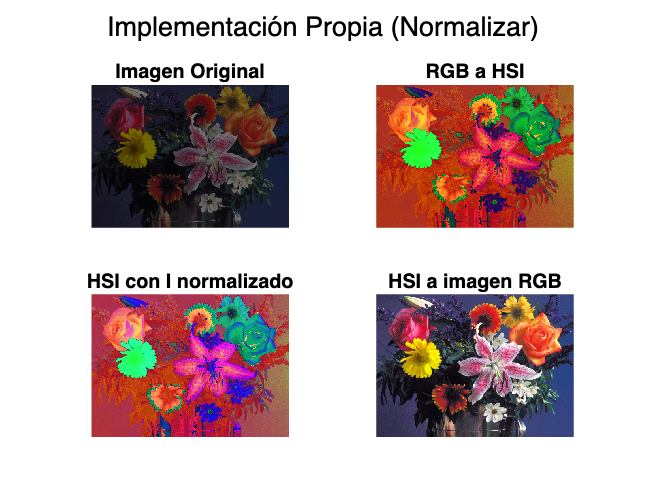

results01 = cell(2, 2);
results01{1,1} = originalImage;
results01{1,2} = rgbTohsi(originalImage);
results01{2,1} = normalizeImage(results01{1,2});
results01{2,2} = hsiTorgb(results01{2,1});
showMultipleImages('Implementación Propia (Normalizar)',results01,{'Imagen Original', 'RGB a HSI', 'HSI con I normalizado', 'HSI a imagen RGB'});

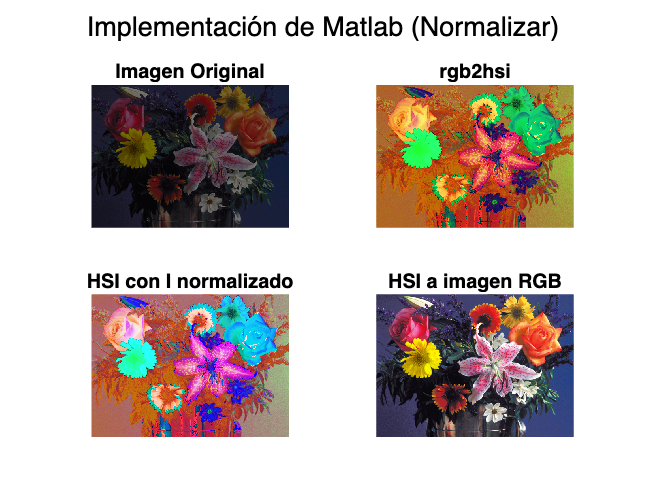

results02 = cell(1, 4);
results02{1,1} = originalImage;
results02{1,2} = rgb2hsv(originalImage);
results02{1,3} = normalizeImage(results02{1,2});
results02{1,4} = hsv2rgb(double(results02{1,3}));
showMultipleImages('Implementación de Matlab (Normalizar)',results02,{'Imagen Original', 'rgb2hsi', 'HSI con I normalizado', 'HSI a imagen RGB'});

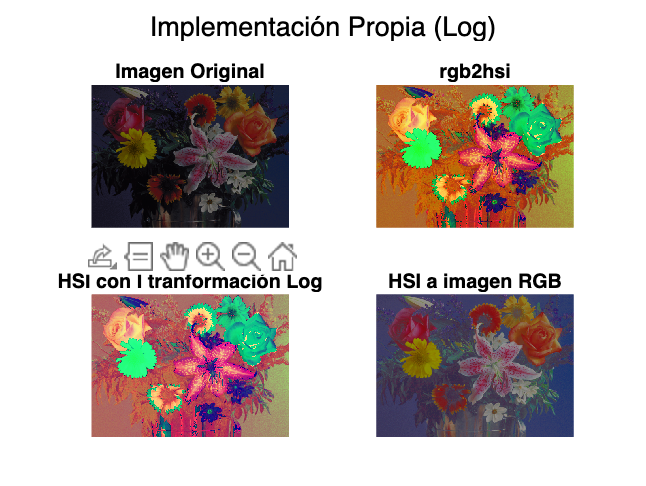

results03 = cell(1, 4);
results03{1,1} = originalImage;
results03{1,2} = rgb2hsv(originalImage);
results03{1,3} = transformLogI(results03{1,2});
results03{1,4} = hsv2rgb(double(results03{1,3}));
showMultipleImages('Implementación Propia (Log)',results03,{'Imagen Original', 'rgb2hsi', 'HSI con I tranformación Log', 'HSI a imagen RGB'});

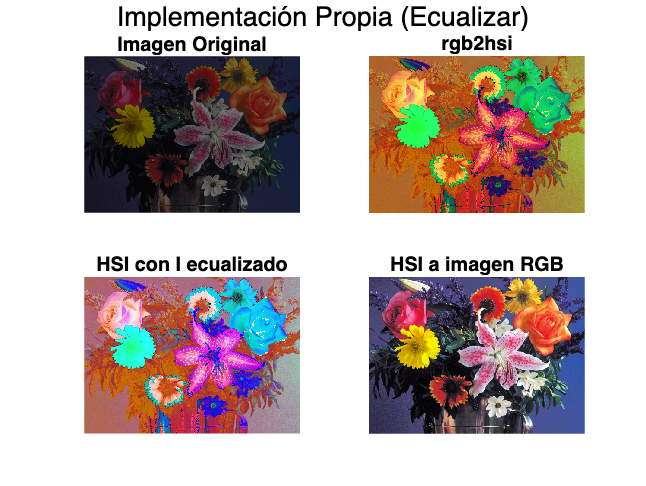

results04 = cell(1, 4);
results04{1,1} = originalImage;
results04{1,2} = rgb2hsv(originalImage);
results04{1,3} = equalizeIntensity(results04{1,2});
results04{1,4} = hsv2rgb(double(results04{1,3}));
showMultipleImages('Implementación Propia (Ecualizar)',results04,{'Imagen Original', 'rgb2hsi', 'HSI con I ecualizado', 'HSI a imagen RGB'});

#### Función para ecualizar la banda de intensidad del modelo HSI

function ecualizedImage = equalizeIntensity(HSI)
    H = HSI(:,:,1);
    S = HSI(:,:,2);
    I = HSI(:,:,3);

    % histograma de la componente de intensidad (I)
    [counts, bins] = imhist(I);
    
    % función de distribución acumulativa (CDF)
    CDF = cumsum(counts) / sum(counts);

    % Mapear los valores de intensidad originales a los valores ecualizados
    I_eq = zeros(size(I));

    for i = 1:length(bins)
        indices = (I >= bins(i));
        I_eq(indices) = CDF(i);
    end

    ecualizedImage = cat(3, H, S, I_eq);
end

function imgLogI = transformLogI(imgHSI)
    % Separar canales de la imagen HSI
    H = imgHSI(:,:,1); 
    S = imgHSI(:,:,2);
    I = imgHSI(:,:,3);
    
    % Aplicar transformacion logaritmica al canal I
    logI = log(I+1.3); 
    
    % Reconstruir imagen HSI con nuevo canal I
    imgLogI = cat(3, H, S, logI);
end

function normalizedImage = normalizeImage(HSI)
 H = HSI(:,:,1);
 S = HSI(:,:,2);
 I = HSI(:,:,3);
 normalizedIntensity = I ./ max(I(:));
 normalizedImage = cat(3, H, S, normalizedIntensity);
end

#### Función para cambiar una imagen de modelo RGB a HSI

function hsi = rgbTohsi(rgb)
    rgb = double(rgb) / 255;
    
    % Separamos la imagen recibida en tres canales
    r = rgb(:,:,1);
    g = rgb(:,:,2);
    b = rgb(:,:,3);
    
    num = 0.5 * ((r - g) + (r - b));
    den = sqrt((r - g).^2 + (r - b).*(g - b));
    theta = acos(num ./ (den + eps));

    % H
    h = theta;
    h(b > g) = 2*pi - h(b > g); 
    h = h / (2*pi);
 
    % Se calcula el componente de saturación
    s = 1 - 3 * min(rgb, [], 3) ./ sum(rgb, 3);
    
    % Componente de intensidad
    i = (r + g + b) / 3;

    hsi = cat(3, h, s, i);
end

#### Función para cambiar una imagen de modelo HSI a RGB

function rgbImage = hsiTorgb(HSI)
    H = HSI(:,:,1); 
    S = HSI(:,:,2); 
    I = HSI(:,:,3); 

    % El rango de tono debe estar entre 0 y 360
    H = H*360;											 
	
    R = zeros(size(H)); 
    G = zeros(size(H)); 
    B = zeros(size(H)); 
    rgbImage = zeros([size(H),3]); % Reconstruir la imagen en los tres canales 
	
    % Sector RG (0◦ ≤ H < 120◦):
    B(H<120) = I(H<120).*(1-S(H<120)); 
    R(H<120) = I(H<120).*(1+((S(H<120).*cosd(H(H<120)))./cosd(60-H(H<120)))); 
    G(H<120) = 3.*I(H < 120) - (R(H < 120) + B(H < 120));	 

    % Si H está en este sector primero le restamos 120
    H2 = H - 120; 
    
    % Sector GB (120◦ ≤ H < 240◦)
    R(H>=120&H<240) = I(H >= 120 & H< 240).*(1-S( H >= 120 & H<240)); 
    G(H>=120&H<240) = I(H >= 120& H< 240).*(1+((S(H>=120&H<240).*cosd(H2(H>=120&H<240)))./cosd(60-H2(H>=120&H<240)))); 
    B(H>=120&H<240) = 3.*I(H>=120&H<240)-(R(H>=120&H<240)+G(H>=120&H<240)); 

    %  Si H está en este sector primero lerestamos 240
    H2 = H - 240; 

    %  Sector RG (240◦ ≤ H ≤ 360◦)
    G(H >= 240 & H <= 360) = I(H >= 240 & H<=360).*(1 - S(H >= 240 & H<=360)); 
    B(H >= 240 & H <= 360) = I(H >= 240 & H<=360).*(1+((S(H >= 240 & H <= 360).*cosd(H2(H>=240&H<=360)))./cosd(60-H2(H>=240&H<=360)))); 
    R(H >= 240 & H <= 360) = 3.*I(H >= 240 & H <= 360) - (G(H >= 240&H<=360)+B(H>=240&H<=360)); 
    
    % Se reconstruye la imagen completa con los valores obtenidos
    rgbImage(:,:,1) = R; 
    rgbImage(:,:,2) = G; 
    rgbImage(:,:,3) = B; 
    
    rgbImage=im2uint8(rgbImage); 
end

#### Función para crear figuras acompañadas de una etiqueta

function showMultipleImages(figure_title, images, image_labels)
    [m,n] = size(images);
    aux = 1;
    for i = 1:m
    for j = 1:n
        subplot(2, 2, aux);
        imshow(images{i,j},[]);
        title(image_labels{aux});
        aux = aux+1;
    end
    end
    sgtitle(figure_title); 
end